close all
clear
clc

Bestem mindste orden for et Butterworth-filter, hvor -3 dB er ved 10 kHz, og der er -60 dB ved 50 kHz.

fp=10*10^3

fp = 10000

fs=50*10^3

fs = 50000

Ap=3

Ap = 3

As=60

As = 60


[n,fn]=buttord(fp,fs,Ap,As,'s')

n = 5

fn = 1.2559e+04

Den mindste orden er således 5.

Bestem intervallet for 3 dB-frekvensen med de stillede krav:

Den minimale værdi for 3 dB-frekvensen er 10 kHz.

Den maksimale værdi for 3 dB-frekvensen er givet som fn af udregningen ovenfor. Den kan også udregnes som:

syms f3dbmax
eq=fs==f3dbmax*nthroot(10^(As/10)-1,2*n);
vpa(solve(eq,f3dbmax))

$$ans = 12559.433413491806654336947726436$$

Intervallet er således fra 10 kHz til 12,6 kHz, hvorfor filteret kan designes til at have en knækfrekvens alt omkring der. Det kan være ønskeligt at pladsere den i midten, så komponenttolerancer ikke er fatale for filterets funktion.

Opskriv overføringsfunktionen (normeret, så wc = 1 og den er opdelt i første- og andenordens):

[z,p,k]=buttap(n);
[num,den]=zp2tf(z,p,k);
Hs=tf(num,den)


Hs =
 
                            1
  -----------------------------------------------------
  s^5 + 3.236 s^4 + 5.236 s^3 + 5.236 s^2 + 3.236 s + 1
 
Continuous-time transfer function.



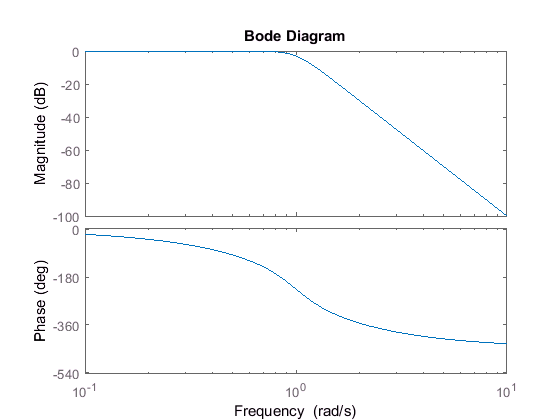

bodeplot(Hs)


sos=zp2sos(z,p,k)

sos =          0    1.0000         0    1.0000    1.0000         0
         0         0    1.0000    1.0000    0.6180    1.0000
         0         0    1.0000    1.0000    1.6180    1.0000
